% AE6511 Final Problem 4
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

syms x_1(t) x_2(t) u
DE1 = diff(x_1,t) == x_2 + u;
DE2 = diff(x_2,t) == -u;

% (A) When u = -1 and IC applied 
IC = [x_1(0) == 0, x_2(0) == -0.5];
DE1A = subs(DE1,u,-1);
DE2A = subs(DE2,u,-1);
[bb1_x1(t), bb1_x2(t)] = dsolve([DE1A DE2A],IC);
expand(bb1_x1)

$$ans(t) = 0.5000\,t^{2}-1.5000\,t$$

bb1_x2

$$bb1\_x2(t) = t-0.5000$$

% (B) When u = 1 and IC applied 
DE1B = subs(DE1,u,1);
DE2B = subs(DE2,u,1);
[bb2_x1(t), bb2_x2(t)] = dsolve([DE1B DE2B],IC);
expand(bb2_x1)

$$ans(t) = 0.5000\,t-0.5000\,t^{2}$$

bb2_x2

$$bb2\_x2(t) = -t-0.5000$$

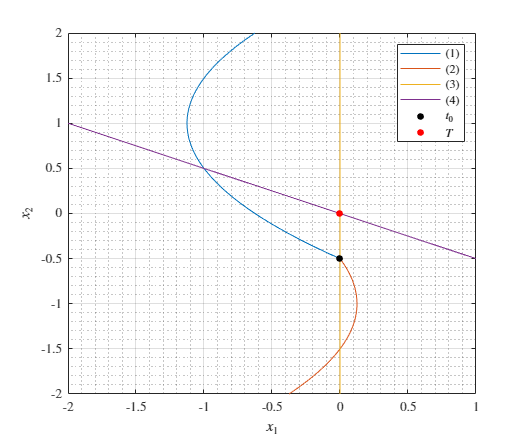

% Optimal trajectories
tspan = linspace(0,4,100);
x2 = linspace(-2,2,100);

% Singular arcs
x1s = -2*x2;
y1s = zeros(size(x2));

fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(bb1_x1(tspan),bb1_x2(tspan),'DisplayName','(1)')
    hold on;
    plot(bb2_x1(tspan),bb2_x2(tspan),'DisplayName','(2)')
    plot(y1s, x2,'DisplayName','(3)')
    plot(x1s, x2,'DisplayName','(4)')
    plot(0,-0.5,'.k','MarkerSize',15,'DisplayName','$t_0$')
    plot(0, 0, '.r', 'MarkerSize', 15,'DisplayName','$T$')
    grid on; grid minor; box on; hold off;
    legend()
    xlabel('$x_1$')
    ylabel('$x_2$')
    xlim([-2,1])
    ylim([-2,2])
saveas(fig,'outputs/p4_all_traj.png')

% Find the optimal trajectory
syms y_1 y_2 
eqn1 = y_1 == 0.5*(y_2+0.5)^2 - 1.5*(y_2+0.5);
eqn2 = y_2 == -0.5*y_1;
sol = solve([eqn1 eqn2], [y_1 y_2])

sol = struct with fields:
    y_1: [2×1 sym]
    y_2: [2×1 sym]


sol.y_1

$$ans = \left(\begin{array}{c} -1\\ 5 \end{array}\right)$$

sol.y_2

$$ans = \left(\begin{array}{c} 0.5000\\ -2.5000 \end{array}\right)$$

% Appropriate intersect
insct.x1 = sol.y_1(1);
insct.x2 = sol.y_2(1);

% Compute the time to the intersect
insct.t = solve([bb1_x1(t)==insct.x1 bb1_x2(t)==insct.x2], t)

insct = struct with fields:
    x1: -1
    x2: 0.5000
     t: 1


% singular 
dX = [diff(x_1,t); diff(x_2,t)];
X = [x_1; x_2];
A = [-1 0; 1 1];
cond = [x_1(1)==-1, x_2(1)==0.5];
sig_traj = dsolve(dX == A*X,cond)

sig_traj = struct with fields:
    x_2: 1.3591*exp(-t)
    x_1: -2.7183*exp(-t)


sig_traj.x_1

$$ans = -2.7183\,{\mathrm{e}}^{-t}$$

sig_traj.x_2

$$ans = 1.3591\,{\mathrm{e}}^{-t}$$

% (b)
% u = 1 bang-bang arc through origin 
syms c_1 c_2 tau
assume(tau, 'positive');
eqn3 = -tau + c_1 == tau - 0.5;
eqn4 = -0.5*tau^2 + (c_1 + 1)*tau + c_2 == 0.5*tau^2 - 1.5*tau;
eqn5 = 0 == -0.5 + 0.5*(c_1 + 1)^2 + c_2;
[c1, c2, tt] = solve([eqn3 eqn4 eqn5], [c_1 c_2 tau]);
c1 = double(c1)

c1 = 2.0811

c2 = double(c2)

c2 = -4.2467

tt = double(tt)

tt = 1.2906

% New boundary 
bb3_x1(t) = -0.5*t^2 + (c1 + 1)*t + c2;
bb3_x2(t) = -t + c1;

tspan1 = linspace(tt,4.5,100);
tspan = linspace(0,4,100);

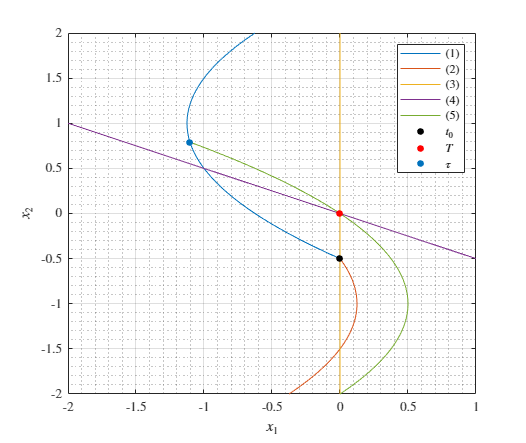

fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(bb1_x1(tspan),bb1_x2(tspan),'DisplayName','(1)')
    hold on;
    plot(bb2_x1(tspan),bb2_x2(tspan),'DisplayName','(2)')
    plot(y1s, x2,'DisplayName','(3)')
    plot(x1s, x2,'DisplayName','(4)')
    plot(bb3_x1(tspan1),bb3_x2(tspan1),'DisplayName','(5)')
    plot(0,-0.5,'.k','MarkerSize',15,'DisplayName','$t_0$')
    plot(0, 0, '.r', 'MarkerSize', 15,'DisplayName','$T$')
    plot(bb3_x1(tt),bb3_x2(tt),'.','MarkerSize',15,'DisplayName','$\tau$')
    grid on; grid minor; box on; hold off;
    legend()
    xlabel('$x_1$')
    ylabel('$x_2$')
    xlim([-2,1])
    ylim([-2,2])
saveas(fig,'outputs/p4_all_traj_new.png')

% (c) 
tau01 = solve([(-0.5*t^2 + (c1 + 1)*t + c2)==0],t);
tau02 = solve((-t + c1)==0,t);
tt0 = double(mean([tau01(1) tau02]))

tt0 = 2.0812

xopt1_x1 = @(t) 0.5 * (0.5*t.^2 - 1.5.*t).^2;
xopt2_x1 = @(t) 0.5 * (-2.7183.*exp(-t)).^2;
Jopt = integral(xopt1_x1,0,double(insct.t)) + integral(xopt2_x1,double(insct.t),inf)

Jopt = 0.4625


xbb1_x1 = xopt1_x1;
xbb2_x1 = @(t) 0.5 * (-0.5*t.^2 + (c1 + 1)*t + c2).^2;
Jbb = integral(xbb1_x1,0,tt) + integral(xbb2_x1,tt,tt0)

Jbb = 0.5144